# Tarea 2 Laboret

## Consigna

De las especificaciones de diseño dadas archivo adjunto (sobrepaso, tiempo de establecimiento 2% y error de régimen ante escalón = 0).

- Obtener los valores de $\zeta \;$, $\omega_0$, $\omega_d$:

$\zeta =\frac{-\ln \left(\frac{S}{100}\right)}{\sqrt{\pi {\;}^2 +{\ln \left(\frac{S}{100}\right)}^2 }}$, $t_R \left(2%\right)=\frac{4}{\zeta \omega_0 }$, $\omega_d =\omega_0 \sqrt{\;1-\zeta^2 }$, $t_d =\frac{2\pi \;}{\omega_d }$

- Calcular la cantidad de muestras por ciclo de la frecuencia amortiguada $\omega_d$:


$$m=\frac{t_d }{T_m }$$


- Mediante la equivalencia de planos s y z determinar la ubicación de los polos deseados en el plano z.


$$r=|z_{1,2} |=e^{-\zeta \;\omega_0 T_m } \Omega =\angle z_{1,2} =\pm \omega_d T_m$$


- Seleccionar y diseñar al menos 2 controlaores digitales en serie (PI, PD, PID o adelanto) que cumplan (para los polos dominantes) las especificaciones dadas mediante SISOTOOL, en caso de que no se cumplan analizar el por qué.

- La condición de error debe cumplirse con exactitud.

- Construir el sistema de lazo cerrado y verificar los polos, ceros y respuesta temporal.

- Simular mediante un diagrama Simulink el control que mejores prestaciones haya obtenido según se muestra en los diagramas adjunto graficando la salida, el error, las acciones de control individuales P, I, D o la de adelanto (las que hubiera) y la acción de control total después del retentor de salida.

## Desarrollo de los controladores

Primero, las funciones de transferencia y constantes involucradas.

G = zpk([],[-2 -3],10)

G =
 
      10
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.
Model Properties


Tm = 0.12;
Gd = c2d(G,Tm,'zoh')

Gd =
 
   0.059115 (z+0.8187)
  ---------------------
  (z-0.7866) (z-0.6977)
 
Sample time: 0.12 seconds
Discrete-time zero/pole/gain model.
Model Properties


tR = 2;
S = 10;
zeta = -log(S/100)/sqrt(pi^2+(log(S/100))^2)

zeta = 0.5912

omega0 = 4/(zeta*tR)

omega0 = 3.3832

omegaD = omega0*sqrt(1-zeta^2)

omegaD = 2.7288

tD = 2*pi/omegaD

tD = 2.3026

r = exp(-zeta*omega0*Tm)

r = 0.7866

omega = omegaD*Tm

omega = 0.3275

La cantidad de muestras por ciclo de la frecuencia amortiguada es:

m = tD/Tm

m = 19.1882

Los polos deseados en el plano z se determinan a continuación:

[r1,ph1] = pol2cart(omega,r)

r1 = 0.7448

ph1 = 0.2530

[r2,ph2] = pol2cart(-omega,r)

r2 = 0.7448

ph2 = -0.2530

p1 = r1+ph1*1i

p1 = 0.7448 + 0.2530i

p2 = r2+ph2*1i

p2 = 0.7448 - 0.2530i

Se muestra a continuación el lugar de raíces de la función de transferencia discreta junto con los polos deseados. Estos últimos son los dibujados en color rojo

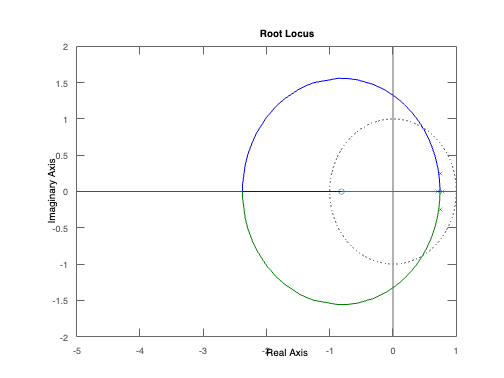

rlocus(Gd)
hold on;
scatter(r1,ph1,'red','x')
scatter(r2,ph2,'red','x')
hold off

Se puede apreciar cómo los polos deseados no forman parte del lugar de raíces, aunque se encuentran cerca. Es necesario lograr desplazar el rlocus() de forma que por él pasen los polos rojos para lograr las especificaciones de sobrepasamiento y tiempo de establecimiento dados. El primer controlador que se diseñará será del tipo PI. Con él se pretende eliminar el error en estado estable con el integrador, y luego, se hará uso de un controlador PID que eliminará el error en estado estable también y añadirá una acción derivativa a la acción de control. Para estos procedimientos se utilizará la herramienta **SISOTOOL. **

Para el primer controlador, es necesario colocar un polo fijo en 1, y luego, el cero móvil se lo utiliza para cancelar el polo, cómo se dijo anteriormente. El cero móvil estará ubicado en $0\ldotp 7866$. Ahora, haciendo uso de SisoTool y la condición de módulo para el controlador se obtiene el controlador deseado.

zAux = 0.7448+0.2530*1i;
Kc = abs((zAux-1)*(zAux-0.6977)/(0.059115*(zAux+0.8187)))

Kc = 0.9877

%C 
z = tf('z');

Se declara C1 de forma auxiliar para evitar el borrado del workspace en una hipotética nueva sesión de trabajo.

C1 = 0.55541*(z-0.7866)/(z-1)

C1 =
 
  0.5554 z - 0.4369
  -----------------
        z - 1
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


Al realimentar el sistema de forma unitaria:

F = feedback(minreal(C1*Gd),1)

F =
 
    0.032833 (z+0.8187) (z-0.7866)
  ----------------------------------
  (z-0.7866) (z^2 - 1.665z + 0.7246)
 
Sample time: 0.12 seconds
Discrete-time zero/pole/gain model.
Model Properties


pole(F)

ans =    0.7866 + 0.0000i
   0.8324 + 0.1779i
   0.8324 - 0.1779i


zero(F)

ans =    -0.8187
    0.7866


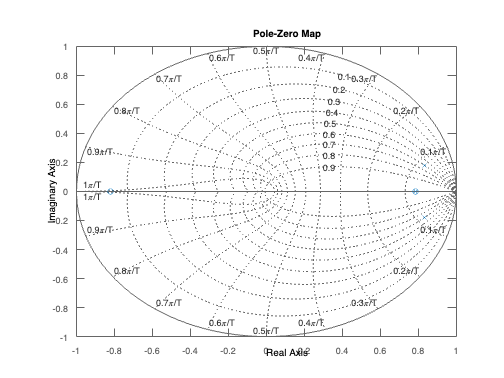

pzmap(F)
grid

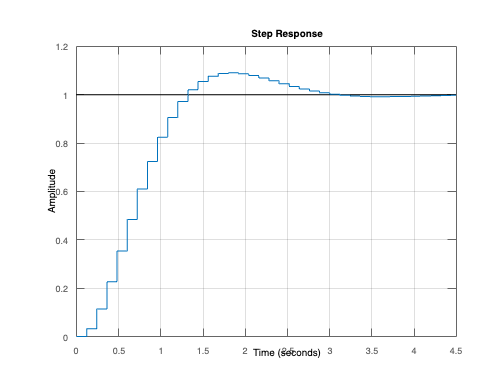

step(F);grid

Se puede apreciar en la gráfica que se cumplen los parámetros de diseño dados. Por alguna razón no se cancelan el polo dominante junto con el cero móvil introducido (pero puede visualizarse en el mapa que aparecen en el mismo punto del plano complejo). Se muestran a continuación los parámetros de la respuesta temporal anteriormente graficada:

stepinfo(F)

ans = struct with fields:
         RiseTime: 0.8400
    TransientTime: 2.7600
     SettlingTime: 2.7600
      SettlingMin: 0.9061
      SettlingMax: 1.0903
        Overshoot: 9.0345
       Undershoot: 0
             Peak: 1.0903
         PeakTime: 1.8000


Ahora se procede con el diseño de un controlador PID. Se cancela el polo no dominante con uno de los ceros, se colocan 2 polos (uno en el origen y otro en 1).

thetaZero = rad2deg(atan(0.2530/(0.7448+0.8187)))

thetaZero = 9.1917

Para aportar un ángulo de 20º con el cero, se puede poner:

d = 0.2530/tan(deg2rad(20))

d = 0.6951

El cero debe estar en:

c = 0.7448-d

c = 0.0497

Se busca la ganancia del controlador a partir de la condición de módulo.

zAux = 0.7448+0.2530*1i;
Kc = 1/abs((0.059115*(zAux+0.8187)*(zAux-c))/((zAux-0.7866)*(zAux-1)*zAux))

Kc = 1.0466

La función de transferencia del PID obtenido es:

%C
PIDController = 0.41772*(z-0.6977)*(z-c)/(z*(z-1))

PIDController =
 
  0.4177 z^2 - 0.3122 z + 0.01448
  -------------------------------
              z^2 - z
 
Sample time: unspecified
Discrete-time transfer function.
Model Properties


Y a lazo cerrado se tiene:

FPID = feedback(minreal(PIDController*Gd),1)

FPID =
 
    0.024694 (z-0.6977) (z+0.8187) (z-0.04969)
  ----------------------------------------------
  (z-0.00125) (z-0.6977) (z^2 - 1.761z + 0.8034)
 
Sample time: 0.12 seconds
Discrete-time zero/pole/gain model.
Model Properties


Ahora el análisis del sistema controlado:

pole(FPID)

ans =    0.0013 + 0.0000i
   0.8803 + 0.1686i
   0.8803 - 0.1686i
   0.6977 + 0.0000i


zero(FPID)

ans =     0.6977
   -0.8187
    0.0497


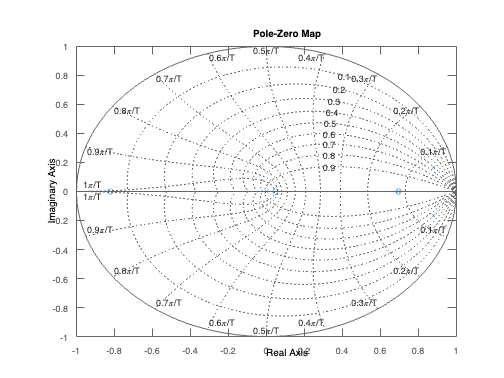

pzmap(FPID);grid

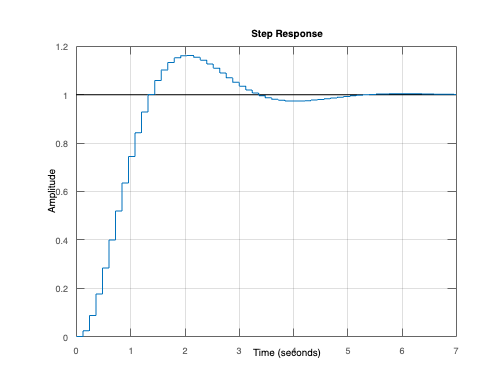

step(FPID);grid

Se muestran a continuación los parámetros de la respuesta temporal anteriormente graficada:

stepinfo(F)

ans = struct with fields:
         RiseTime: 0.8400
    TransientTime: 2.7600
     SettlingTime: 2.7600
      SettlingMin: 0.9061
      SettlingMax: 1.0903
        Overshoot: 9.0345
       Undershoot: 0
             Peak: 1.0903
         PeakTime: 1.8000
